# Figure 4: S_EE and S_II

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData/FigureD1'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];
Panel2 = length(S_IItest); Panel1 = 1;
S_ElgnInd = 2; % NEED TO CHANGE TO 2!
S_IlgnInd = 2; % $(seq 2 4)
rI_L6Ind = 2;  % 3 6
S_EEInd = 3;

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

Fig1 = figure('Name','FigD1','units','normalized','outerposition',[0 0 .80 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .01],[.05 .03],[.08 .1]);

    S_EE = S_EEtest(3);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('FigContourUnInd_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/FigureD1/' CurrentPanelFile])
        load(sprintf('FigContourUnInd_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end

        % First axis for fr
        axes(ha(S_IIInd));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrEShow = CurrentFrE;
        CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrEShow(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        % set ticks, labels, titles, etc for axis1.
        ax = gca;
        if S_IIInd == 1
           
            ax.YAxis.FontSize = 13;
            ylabel('S^{EI}/S^{EE}','FontSize',16)

        else
            set(gca,'yticklabel','')
        end
              
            ax.XAxis.FontSize = 13;            
            xlabel('S^{IE}','FontSize',16);
     
        axis square
        axis tight
        
        title(sprintf('S^{II}=%.3f',S_II),'FontSize',16) 
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        hold on
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
%         GreyHem = 0.5*ones(size(CurrentFrE));
%         if NoFailWeight<0.11 || SIEWeight<1 % if impossible pattern show up on the left...
%             FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
%             
%             
%             
%         end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        
%         % Midpoint of Good Area
%         CurrentFrEGA = CurrentFrE;
%         CurrentFrEGA(CurrentFrE<=3 | CurrentFrE>=5 | ...
%             CurrentFrI./CurrentFrE    <=3 | ...
%             CurrentFrI./CurrentFrE    >=4.25) = nan;
%         CurrentFrEGA(FailMap) = nan;
%         GoodArea = (~isnan(CurrentFrEGA));
%         
%         GAratio = sum(double(GoodArea),'all')/(length(CurrentFrEGA(:)))
%         if GAratio<0.007 % skip midpoint if too small
%             disp('Good Area too small, Exit.')
%         else
%             [GA_SEIInd,GA_SIEInd,~] = find(GoodArea);
%             MP_SEI = ContourData_7D.S_EItest(floor(mean(GA_SEIInd)))/S_EE;
%             MP_SIE = ContourData_7D.S_IEtest(floor(mean(GA_SIEInd)))/S_II;
%             scatter(MP_SIE,MP_SEI, 1000, 'k+','LineWidth',2)
%         end
        
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        axis([min(ContourData_7D.S_IEtest) max(ContourData_7D.S_IEtest) ...
              min(ContourData_7D.S_EItest/S_EE) max(ContourData_7D.S_EItest/S_EE)])
        
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        
        sprintf('id1 = %.2f, id2 = %.2f, Fail = %.2f, SIEWgt = %.2f',...
                S_EE,S_II,NoFailWeight,SIEWeight)
        
%             if S_EEInd == length(S_EEtest)
%                 if S_IIInd == 1
%                     Pos1 = get(gca,'Position');
%                 elseif S_IIInd == length(S_IItest)
%                     Pos2 = get(gca,'Position');
%                 end
%             end   
    end

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.39, SIEWgt = 0.95'

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.62, SIEWgt = 1.10'

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.65, SIEWgt = 1.27'

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.56, SIEWgt = 1.37'

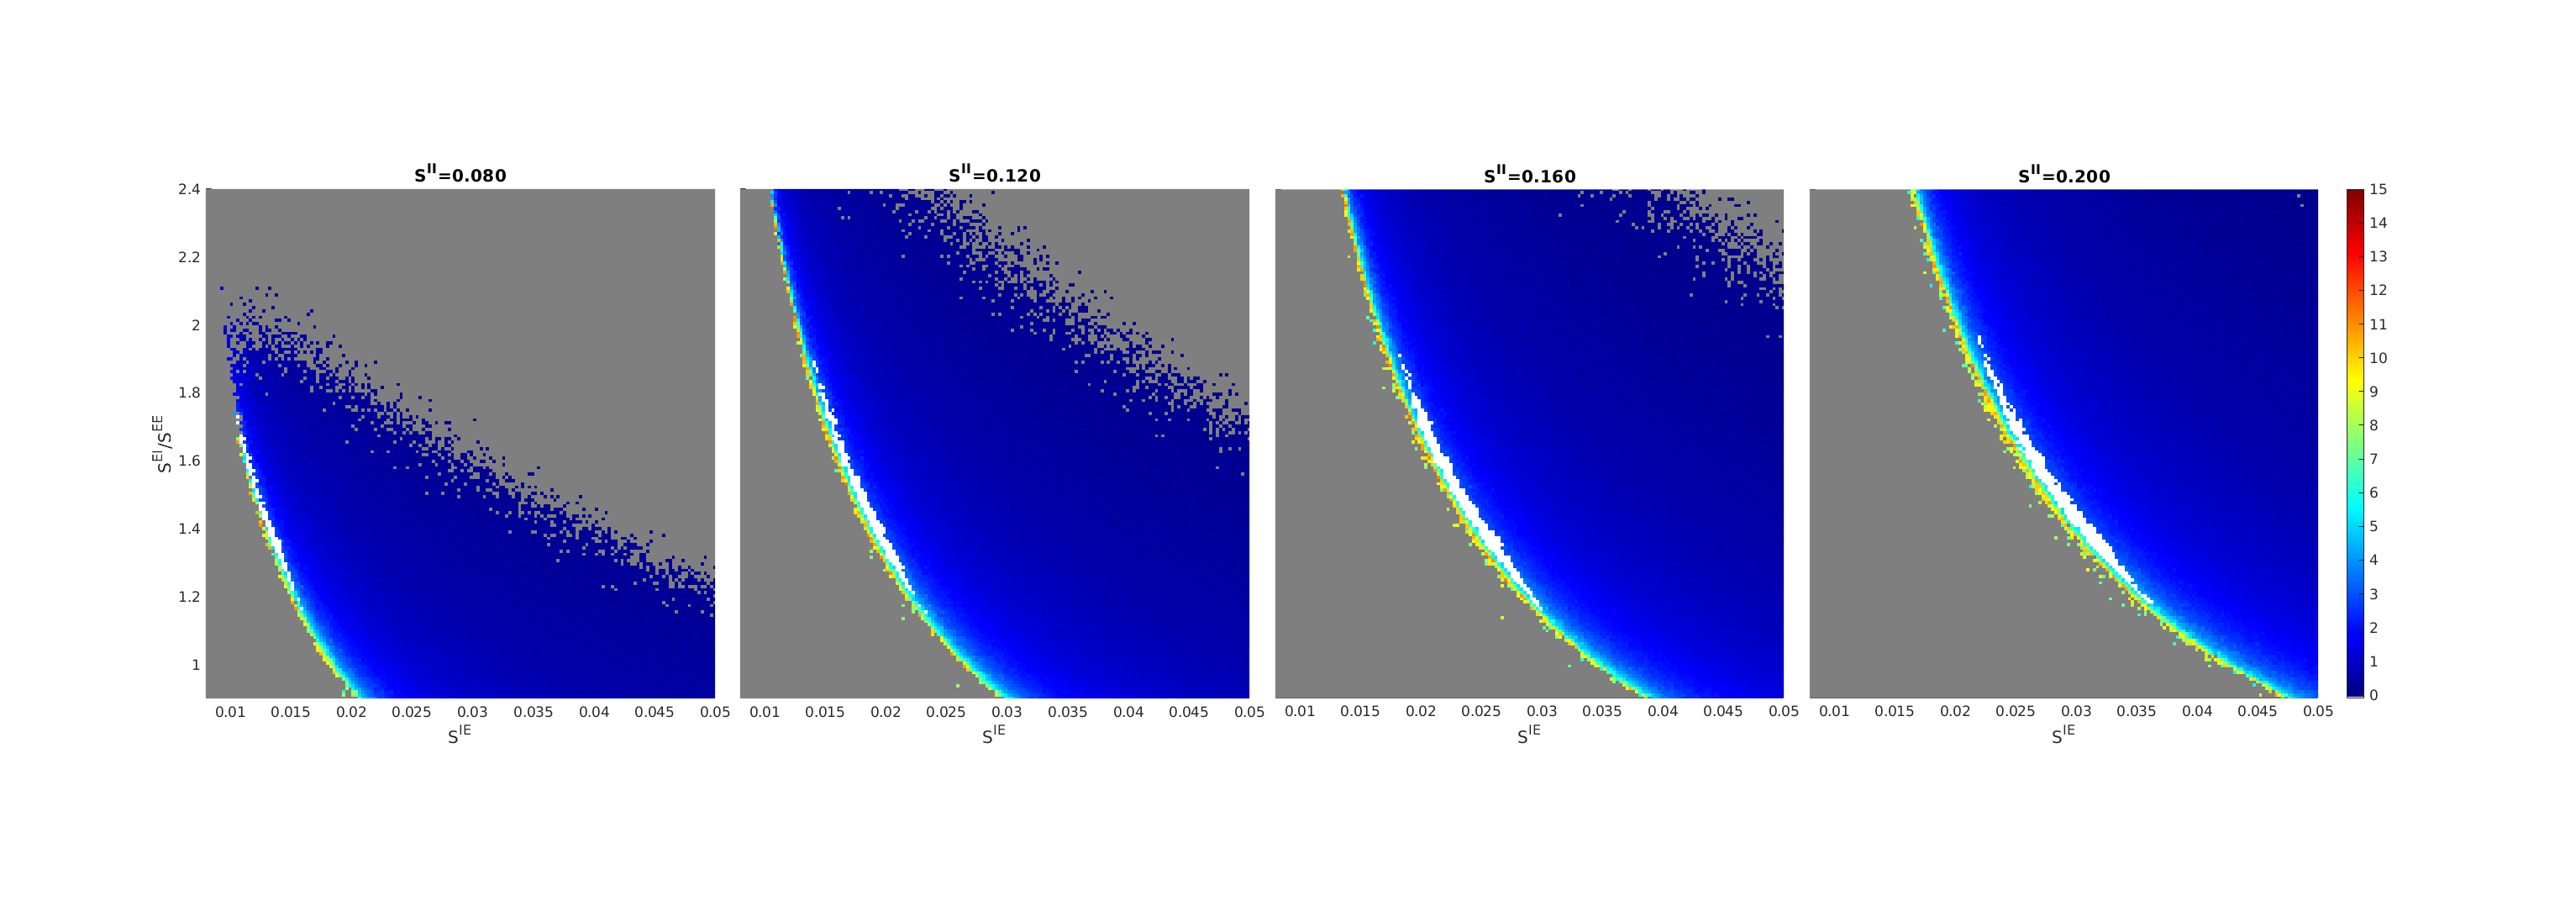

Pos2 = get(ax1a,'Position');
cbr = colorbar(ax1a);
set(ax1a,'Position',Pos2)
caxis([0 15])
set(cbr,'YTick',0:15,'FontSize',13)

Save figures

FigurePaperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'FigureD1';
savefig(Fig1,[FigurePaperpath FigName1 '.fig']);


Print Figs

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [40,28];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[FigurePaperpath FigName1 '.pdf'],'Resolution',600)
